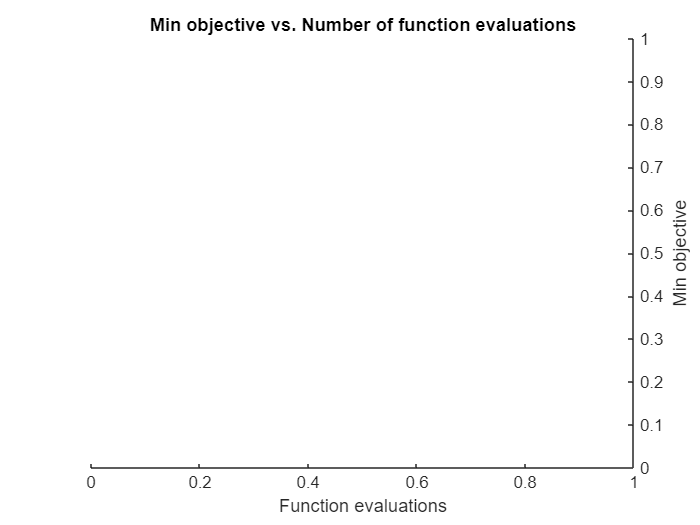

---
[06-Sep-2025 04:38:57] BO trial: num_factors=97, lambda=0.00015518, lr=0.00028267, neg_ratio=4, batch_size=913


% === Load data ===
load('out/train.mat');   % R_train, train_u, train_i, train_ctx
load('out/val.mat');     % val_u, val_i, val_ctx
load('out/test.mat');    % test_u, test_i, test_ctx

if ~isfolder('out/logistic')
    mkdir('out/logistic');
end
logFile = fullfile('out', 'logistic', 'log.txt');
fid = fopen(logFile, 'a');  % 'a' = append to file
addpath("Logistic\")
% === Define objective function for Bayesian Optimization ===
objectiveFcn = @(params) logistic_obj(params, R_train, val_u, val_i);

% === Define search space ===
vars = [
    optimizableVariable('num_factors',[16,128],'Type','integer')
    optimizableVariable('lambda',[1e-4,1e-1],'Transform','log')
    optimizableVariable('lr',[1e-4,1e-1],'Transform','log')
    optimizableVariable('neg_ratio',[1,10],'Type','integer')
    optimizableVariable('batch_size',[256,4096],'Type','integer')
];

% === Run Bayesian Optimization ===
results = bayesopt(objectiveFcn, vars, ...
    'MaxObjectiveEvaluations', 20, ...
    'AcquisitionFunctionName','expected-improvement-plus', ...
    'Verbose',1, ...
    'UseParallel',false);


best_params = results.XAtMinObjective;
fprintf('[%s] Best params found:\n', string(datetime('now')));
disp(best_params);
fprintf(fid,'[%s] Best params found:\n', string(datetime('now')));
fprintf(fid,'%s\n', evalc('disp(best_params)'));


% === Final training with best params (train+val together) ===
R_trainval = R_train + sparse(val_u, val_i, 1, size(R_train,1), size(R_train,2));
num_epochs = 10;
[U, V] = logistic_mf2(R_trainval, ...
    round(best_params.num_factors), ...
    best_params.lambda, ...
    best_params.lr, ...
    num_epochs, ...
    round(best_params.neg_ratio), ...
    round(best_params.batch_size));

[06-Sep-2025 04:41:30] Epoch 1/10 completed in 96.63 sec (1.61 min)
[06-Sep-2025 04:43:15] Epoch 2/10 completed in 105.11 sec (1.75 min)
[06-Sep-2025 04:45:22] Epoch 3/10 completed in 126.27 sec (2.10 min)
[06-Sep-2025 04:47:32] Epoch 4/10 completed in 129.94 sec (2.17 min)
[06-Sep-2025 04:49:41] Epoch 5/10 completed in 129.08 sec (2.15 min)
[06-Sep-2025 04:51:45] Epoch 6/10 completed in 124.66 sec (2.08 min)
[06-Sep-2025 04:53:49] Epoch 7/10 completed in 123.72 sec (2.06 min)
[06-Sep-2025 04:55:53] Epoch 8/10 completed in 123.59 sec (2.06 min)
[06-Sep-2025 04:57:56] Epoch 9/10 completed in 123.44 sec (2.06 min)
[06-Sep-2025 05:00:04] Epoch 10/10 completed in 127.45 sec (2.12 min)


% === Evaluate on test ===
fprintf('[%s] Final evaluation on test started\n', string(datetime('now')));

[06-Sep-2025 05:00:04] Final evaluation on test started


fprintf(fid,'[%s] Final evaluation on test started\n', string(datetime('now')));
[recall20, ndcg20] = evaluate(U, V, test_u, test_i, R_trainval);
fprintf('[%s] Final evaluation ended\n', string(datetime('now')));

[06-Sep-2025 05:07:06] Final evaluation ended


fprintf(fid,'[%s] Final evaluation ended\n', string(datetime('now')));
fprintf('Recall@20 = %.6f\n', recall20);

Recall@20 = 0.951010


fprintf(fid,'Recall@20 = %.6f\n', recall20);
fprintf('NDCG@20   = %.6f\n', ndcg20);

NDCG@20   = 0.705560


fprintf(fid,'NDCG@20   = %.6f\n', ndcg20);

% === Save final model ===
save(fullfile('out/logistic', 'logistic_mf_bo.mat'), ...
    'U', 'V', 'recall20', 'ndcg20', 'best_params');
fclose(fid);


function objective = logistic_obj(params, R_train, val_u, val_i)
%LOGISTIC_OBJ Objective wrapper for bayesopt
%   objective = logistic_obj(params, R_train, val_u, val_i)
%
%   Returns negative NDCG@20 (to be minimized)

    logDir = fullfile('out','logistic');
    if ~isfolder(logDir)
        mkdir(logDir);
    end
    logFile = fullfile(logDir, 'bo_log.txt');
    fid = fopen(logFile, 'a');

    % Extract params (table or struct)
    if istable(params)
        num_factors = round(params.num_factors);
        lambda      = params.lambda;
        lr          = params.lr;
        neg_ratio   = round(params.neg_ratio);
        batch_size  = round(params.batch_size);
    else
        num_factors = round(params.num_factors);
        lambda      = params.lambda;
        lr          = params.lr;
        neg_ratio   = round(params.neg_ratio);
        batch_size  = round(params.batch_size);
    end

    num_epochs = 10;
    tStart = tic;
    trial_ts = string(datetime('now'));
    if fid>0
        fprintf(fid, '---\n[%s] BO trial: num_factors=%d, lambda=%.5g, lr=%.5g, neg_ratio=%d, batch_size=%d\n', ...
            trial_ts, num_factors, lambda, lr, neg_ratio, batch_size);
        fprintf( '---\n[%s] BO trial: num_factors=%d, lambda=%.5g, lr=%.5g, neg_ratio=%d, batch_size=%d\n', ...
            trial_ts, num_factors, lambda, lr, neg_ratio, batch_size);
    end

    try
        % Train
        [U, V] = logistic_mf2(R_train, num_factors, lambda, lr, num_epochs, neg_ratio, batch_size);

        % Evaluate on validation set
        [recall_val, ndcg_val] = evaluate(U, V, val_u, val_i, R_train);

        objective = -double(ndcg_val*recall_val);  % maximize NDCG

        elapsed = toc(tStart);
        if fid>0
            fprintf(fid, '[%s] Done in %.2fs: Recall@20=%.6f, NDCG@20=%.6f, obj=%.6g\n\n', ...
                string(datetime('now')), elapsed, recall_val, ndcg_val, objective);
            fprintf( '[%s] Done in %.2fs: Recall@20=%.6f, NDCG@20=%.6f, obj=%.6g\n\n', ...
                string(datetime('now')), elapsed, recall_val, ndcg_val, objective);
            fclose(fid);
        end
        if ~isfinite(objective), objective = Inf; end

    catch ME
        elapsed = toc(tStart);
        if fid>0
            fprintf(fid, '[%s] ERROR after %.2fs: %s\n', string(datetime('now')), elapsed, ME.message);
            fclose(fid);
        end
        objective = Inf;
    end
end
